# DSZOB, cvičenie 6.

## **Zadanie:**

## **Úloha 1 **Filtrácia signálu gaussovským filtrom v časovej i frekvenčnej doméne

**a)**

- definujte fitracne jadro ako gaussovsku funkciu o dĺžke n (napr. 32 alebo 64)

- použite konvolúciu (funkciu **conv**) na filtrovanie signálu týmto gaussovským filtračným jadrom

**b)**

- vypočítajte spektrum filtračného jadra

- týmto spektrom filtračného jadra vynásobte (po prvkoch) spektrum vstupného signálu

- výstup dajte na vstup spätnej transformácii

Porovnavjte tieto dva spôsoby filtrácie !

Ako vstupný signál použite ľubovoľný signál zvuku alebo syntetizovaný zvuk so šumom.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

**a)**

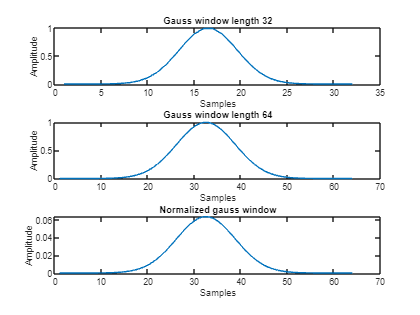

% Riesenie / Solution
clear;
fado = audioread("Asignments\Assignment_3\fado1.wav");
fado_info = audioinfo("Asignments\Assignment_3\fado1.wav");
fs = fado_info.SampleRate;
time_axis = 0:1/fs:fado_info.Duration;
time_axis(end) = [];    % Fix for rounding issue

fado_sample = fado(fs*2:fs*2+1024); % 1024 samples starting from second 2 

gauss_window_32 = gausswin(32, 5);
gauss_window_64 = gausswin(64, 5);

subplot(3,1,1);
plot(gauss_window_32);
title('Gauss window length 32');
xlabel('Samples');
ylabel('Amplitude');
subplot(3,1,2);
plot(gauss_window_64);
title('Gauss window length 64');
xlabel('Samples');
ylabel('Amplitude');
normalized_gauss_window_64 =  gauss_window_64 / sum(gauss_window_64);
subplot(3,1,3);
plot(normalized_gauss_window_64);
title('Normalized gauss window');
xlabel('Samples');
ylabel('Amplitude');

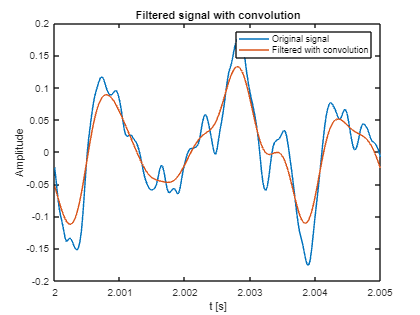

close all;
plot(time_axis(fs*2:fs*2+1024), fado_sample); hold on;
xlim([2, 2.005]);   % Even smaller window for better visibility

filtered_conv = conv(fado_sample, normalized_gauss_window_64, "same");
plot(time_axis(fs*2:fs*2+1024), filtered_conv); hold off;
legend(["Original signal", "Filtered with convolution"]);
title('Filtered signal with convolution');
xlabel('t [s]');
ylabel('Amplitude');

b)

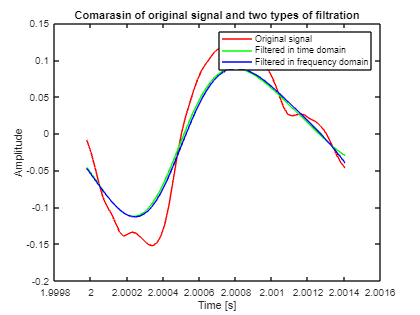

fft_fado = fft(fado_sample(1:64));
fft_gauss = fft(normalized_gauss_window_64);

plot(time_axis(fs*2:fs*2+63), fado_sample(1:64), "red"); hold on;
plot(time_axis(fs*2:fs*2+63), filtered_conv(1:64), "green"); hold on;
plot(time_axis(fs*2:fs*2+63), ifft(abs(fft_gauss) .* fft_fado), "blue");
xlabel("Time [s]")
ylabel("Amplitude")
legend(["Original signal", "Filtered in time domain", "Filtered in frequency domain"]);
title("Comarasin of original signal and two types of filtration");
hold off;

**Answer: **Filtering in time domain and in frequency domain give the same result as can be seen on plot above

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

a) LP filter

- Filtrujte signál v spektrálnej oblasti za pomoci LP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

b) HP filter

- Filtrujte signál v spektrálnej oblasti za pomoci HP filtra (celý signál cez okienka)

- Použite rôzne hraničné hodnoty frekvencie (cut-off freqency)

- Vizualizujte spektrogramom. Frekvenčná osa má byť preškálovaná na frekvencie v Hz!

Ako vstupné dáta použite:

- zvukový signál ladičky

- zvukový signál hudby

- zvukový signál reči

Vyhodnoťte zmenu kvality vypočutého filtrovaného zvuku pre rôzne typy  vstupného signálu a rôzne filtre. Nájdite hraničné  frekvencie pre LP a  HP, pri ktorej je reč na nahrávke ešte zrozumiteľná. Nezabudnite na to,  že pri filtrácií volíte hraničnú frekvenciu, nie hraničný spektrálny koeficient. Je teda nutné previesť indexy spektrálnych koeficientov na  frekvenciu.

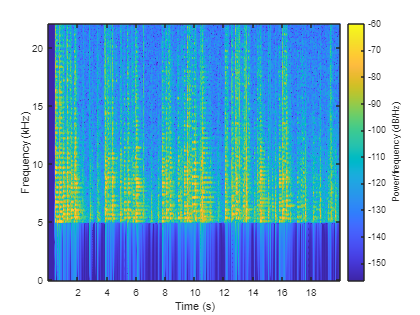

% Riesenie / Solution
spectrogram(hp_filter(fado, length(fado)/100, 5000, fs), hamming(512), 256, 512, fs, 'yaxis');

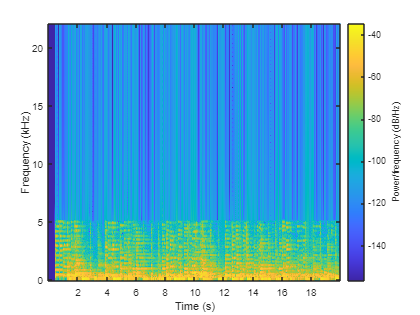

spectrogram(lp_filter(fado, length(fado)/100, 5000, fs), hamming(512), 256, 512, fs, 'yaxis');

% Functions

function new_sig = hp_filter(original, window_len, treshold, fs)
    new_sig = zeros(1,length(original));
    fq = ((1:window_len)*(fs/2)) / window_len;
    for index = 1:window_len:length(original)
        window_dct = dct(original(index:index + window_len - 1));
        for index_dct = 1:length(window_dct)
            if fq(index_dct) < treshold
                window_dct(index_dct) = 0;
            end
        end
        new_sig(index:index + window_len - 1) = idct(window_dct);
    end
end

function new_sig = lp_filter(original, window_len, treshold, fs)
    new_sig = zeros(1,length(original));
    fq = ((1:window_len)*(fs/2)) / window_len;
    for index = 1:window_len:length(original)
        window_dct = dct(original(index:index + window_len - 1));
        for index_dct = 1:length(window_dct)
            if fq(index_dct) > treshold
                window_dct(index_dct) = 0;
            end
        end
        new_sig(index:index + window_len - 1) = idct(window_dct);
    end
end